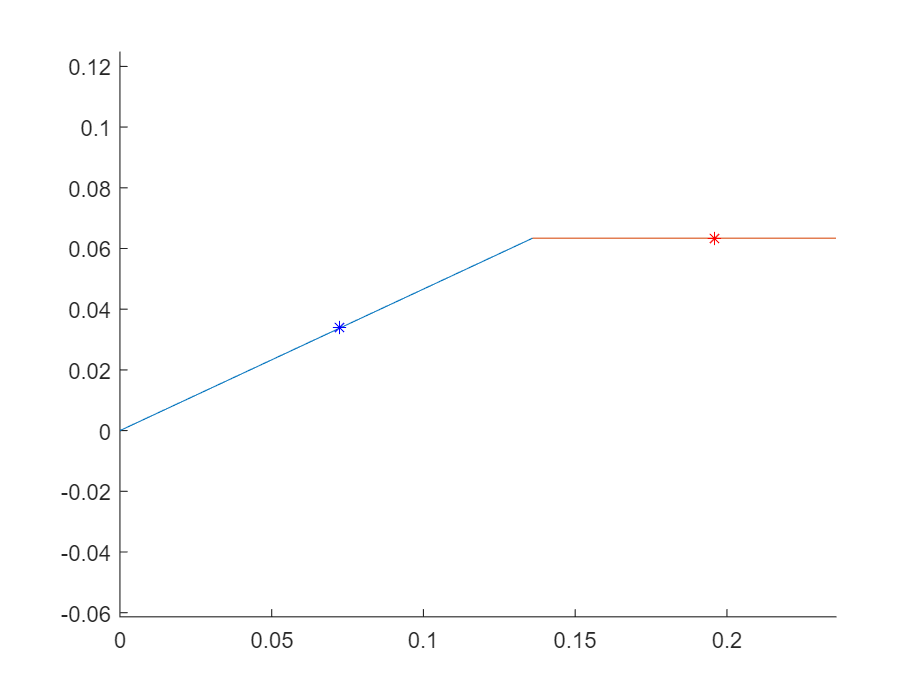

theta_B = 0;
theta_K = 0;
L_1 = 0.15;
L_2 = 0.1;
G_1 = 0.08;
G_2 = 0.06;

% syms theta_B theta_K
% syms L_1 L_2 G_1 G_2
% syms psi_1 psi_2
% theta_1 = 45;
% theta_2 = 45;
% psi_1 = theta_1 - theta_B
% psi_2 = -180+theta_K+theta_2+psi_1
psi_1 = 25;
psi_2 = 0;

r_O = [0; 0];
r_O_A = G_1*[cosd(psi_1); sind(psi_1);];
r_O_B = L_1*[cosd(psi_1); sind(psi_1);];
r_O_C = [L_1*cosd(psi_1)+G_2*cosd(psi_2); L_1*sind(psi_1)+G_2*sind(psi_2);];
r_O_D = [L_1*cosd(psi_1)+L_2*cosd(psi_2); L_1*sind(psi_1)+L_2*sind(psi_2);];

figure
cla, hold on
axis equal
link_1 = [r_O r_O_B];
plot(link_1(1,:),link_1(2,:))
link_2 = [r_O_B r_O_D];
plot(link_2(1,:),link_2(2,:))

plot(r_O_A(1,:),r_O_A(2,:),'b*')
plot(r_O_C(1,:),r_O_C(2,:),'r*')

Dynamics Derivation For Standard Serial Joints

syms theta_B theta_K g
syms L_1 L_2 G_1 G_2 m_1 m_2 I_1 I_2
syms psi_1 psi_dot_1 psi_ddot_1 psi_2 psi_dot_2 psi_ddot_2
syms tau_1 tau_2

custom_vars = [L_1 L_2 G_1 G_2 m_1 m_2 I_1 I_2];

syms m L
dp_vars = [L L L/2 L/2 m m 1/12*m*L^2 1/12*m*L^2];

r_O = [0; 0];
r_O_A = G_1*[cos(psi_1); sin(psi_1);]

$$r\_O\_A = \left(\begin{array}{c} G_{1}\,\cos\left(\psi_{1}\right)\\ G_{1}\,\sin\left(\psi_{1}\right) \end{array}\right)$$

r_O_B = L_1*[cos(psi_1); sin(psi_1);]

$$r\_O\_B = \left(\begin{array}{c} L_{1}\,\cos\left(\psi_{1}\right)\\ L_{1}\,\sin\left(\psi_{1}\right) \end{array}\right)$$

r_O_C = [L_1*cos(psi_1)+G_2*cos(psi_2); L_1*sin(psi_1)+G_2*sin(psi_2);]

$$r\_O\_C = \left(\begin{array}{c} G_{2}\,\cos\left(\psi_{2}\right)+L_{1}\,\cos\left(\psi_{1}\right)\\ G_{2}\,\sin\left(\psi_{2}\right)+L_{1}\,\sin\left(\psi_{1}\right) \end{array}\right)$$

r_O_D = [L_1*cos(psi_1)+L_2*cos(psi_2); L_1*sin(psi_1)+L_2*sin(psi_2);]

$$r\_O\_D = \left(\begin{array}{c} L_{1}\,\cos\left(\psi_{1}\right)+L_{2}\,\cos\left(\psi_{2}\right)\\ L_{1}\,\sin\left(\psi_{1}\right)+L_{2}\,\sin\left(\psi_{2}\right) \end{array}\right)$$


omega_1 = [0; 0; psi_dot_1];
V_A = cross_2d(omega_1,r_O_A)

$$V\_A = \left(\begin{array}{c} -G_{1}\,{\dot{\psi }}_{1}\,\sin\left(\psi_{1}\right)\\ G_{1}\,{\dot{\psi }}_{1}\,\cos\left(\psi_{1}\right) \end{array}\right)$$

omega_2 = [0; 0; psi_dot_2];
V_C = cross_2d(omega_1,r_O_C) + cross_2d(omega_2,r_O_C-r_O_B)

$$V\_C = \left(\begin{array}{c} -{\dot{\psi }}_{1}\,\left(G_{2}\,\sin\left(\psi_{2}\right)+L_{1}\,\sin\left(\psi_{1}\right)\right)-G_{2}\,{\dot{\psi }}_{2}\,\sin\left(\psi_{2}\right)\\ {\dot{\psi }}_{1}\,\left(G_{2}\,\cos\left(\psi_{2}\right)+L_{1}\,\cos\left(\psi_{1}\right)\right)+G_{2}\,{\dot{\psi }}_{2}\,\cos\left(\psi_{2}\right) \end{array}\right)$$


V_A_mag_sq = mag_2d(V_A)^2

$$V\_A\_mag\_sq = {G_{1}}^{2}\,{{\dot{\psi }}_{1}}^{2}$$

V_C_mag_sq = mag_2d(V_C)^2

$$V\_C\_mag\_sq = {\left({\dot{\psi }}_{1}\,\left(G_{2}\,\sin\left(\psi_{2}\right)+L_{1}\,\sin\left(\psi_{1}\right)\right)+G_{2}\,{\dot{\psi }}_{2}\,\sin\left(\psi_{2}\right)\right)}^{2}+{\left({\dot{\psi }}_{1}\,\left(G_{2}\,\cos\left(\psi_{2}\right)+L_{1}\,\cos\left(\psi_{1}\right)\right)+G_{2}\,{\dot{\psi }}_{2}\,\cos\left(\psi_{2}\right)\right)}^{2}$$


V_C_mag_sq = simplify(expand(V_C_mag_sq))

$$V\_C\_mag\_sq = {G_{2}}^{2}\,{{\dot{\psi }}_{1}}^{2}+2\,{G_{2}}^{2}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{G_{2}}^{2}\,{{\dot{\psi }}_{2}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{{\dot{\psi }}_{1}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{L_{1}}^{2}\,{{\dot{\psi }}_{1}}^{2}$$


T_trans = 1/2*m_1*V_A_mag_sq + 1/2*m_2*V_C_mag_sq

$$T\_trans = \frac{m_{2}\,\left({G_{2}}^{2}\,{{\dot{\psi }}_{1}}^{2}+2\,{G_{2}}^{2}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{G_{2}}^{2}\,{{\dot{\psi }}_{2}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{{\dot{\psi }}_{1}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{L_{1}}^{2}\,{{\dot{\psi }}_{1}}^{2}\right)}{2}+\frac{{G_{1}}^{2}\,m_{1}\,{{\dot{\psi }}_{1}}^{2}}{2}$$

T_rot = 1/2*I_1*psi_dot_1^2 + 1/2*I_2*psi_dot_2^2

$$T\_rot = \frac{I_{1}\,{{\dot{\psi }}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{\psi }}_{2}}^{2}}{2}$$

T = T_trans + T_rot

$$T = \frac{m_{2}\,\left({G_{2}}^{2}\,{{\dot{\psi }}_{1}}^{2}+2\,{G_{2}}^{2}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{G_{2}}^{2}\,{{\dot{\psi }}_{2}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{{\dot{\psi }}_{1}}^{2}+2\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+{L_{1}}^{2}\,{{\dot{\psi }}_{1}}^{2}\right)}{2}+\frac{I_{1}\,{{\dot{\psi }}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{\psi }}_{2}}^{2}}{2}+\frac{{G_{1}}^{2}\,m_{1}\,{{\dot{\psi }}_{1}}^{2}}{2}$$

V = m_1*g*G_1*sin(psi_1) + m_2*g*(L_1*sin(psi_1) + G_2*sin(psi_2))

$$V = g\,m_{2}\,\left(G_{2}\,\sin\left(\psi_{2}\right)+L_{1}\,\sin\left(\psi_{1}\right)\right)+G_{1}\,g\,m_{1}\,\sin\left(\psi_{1}\right)$$


lagrange = T-V;
dp_lagrange = simplify(subs(lagrange,custom_vars,dp_vars))

$$dp\_lagrange = \frac{L\,m\,\left(19\,L\,{{\dot{\psi }}_{1}}^{2}+4\,L\,{{\dot{\psi }}_{2}}^{2}-36\,g\,\sin\left(\psi_{1}\right)-12\,g\,\sin\left(\psi_{2}\right)+12\,L\,{{\dot{\psi }}_{1}}^{2}\,\cos\left(\psi_{1}-\psi_{2}\right)+6\,L\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}+12\,L\,{\dot{\psi }}_{1}\,{\dot{\psi }}_{2}\,\cos\left(\psi_{1}-\psi_{2}\right)\right)}{24}$$

q_diff = [psi_1 psi_dot_1 psi_ddot_1; psi_2 psi_dot_2 psi_ddot_2];
Q = [tau_1; tau_2];
EOM = calc_lagrange(lagrange,q_diff,Q)

$$EOM = \left(\begin{array}{c} \left(m_{1}\,{G_{1}}^{2}+m_{2}\,{G_{2}}^{2}+2\,m_{2}\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,L_{1}+m_{2}\,{L_{1}}^{2}+I_{1}\right)\,{\ddot{\psi }}_{1}+\left(-G_{2}\,L_{1}\,m_{2}\,\sin\left(\psi_{1}-\psi_{2}\right)\right)\,{{\dot{\psi }}_{1}}^{2}+\left(2\,G_{2}\,L_{1}\,m_{2}\,{\dot{\psi }}_{2}\,\sin\left(\psi_{1}-\psi_{2}\right)\right)\,{\dot{\psi }}_{1}+m_{2}\,{\ddot{\psi }}_{2}\,{G_{2}}^{2}+L_{1}\,m_{2}\,\sin\left(\psi_{1}-\psi_{2}\right)\,G_{2}\,{{\dot{\psi }}_{2}}^{2}+L_{1}\,m_{2}\,{\ddot{\psi }}_{2}\,\cos\left(\psi_{1}-\psi_{2}\right)\,G_{2}+G_{1}\,g\,m_{1}\,\cos\left(\psi_{1}\right)+L_{1}\,g\,m_{2}\,\cos\left(\psi_{1}\right)=\tau_{1}\\ \left(m_{2}\,{G_{2}}^{2}+I_{2}\right)\,{\ddot{\psi }}_{2}+{G_{2}}^{2}\,m_{2}\,{\ddot{\psi }}_{1}+G_{2}\,g\,m_{2}\,\cos\left(\psi_{2}\right)-2\,G_{2}\,L_{1}\,m_{2}\,{{\dot{\psi }}_{1}}^{2}\,\sin\left(\psi_{1}-\psi_{2}\right)+G_{2}\,L_{1}\,m_{2}\,{\ddot{\psi }}_{1}\,\cos\left(\psi_{1}-\psi_{2}\right)=\tau_{2} \end{array}\right)$$

function out = cross_2d(vec1,vec2)
switch(length(vec1))
    case 1
        vec1 = [0; 0; vec1];
    case 2
        vec1 = [vec1; 0];
end
switch(length(vec2))
    case 1
        vec2 = [0; 0; vec2];
    case 2
        vec2 = [vec2; 0];
end
out = cross(vec1,vec2);
out = out(1:2);
end

function out = mag_2d(vec)
assert(length(vec)==2)
out = simplify(sqrt(vec(1).^2+vec(2).^2));
end